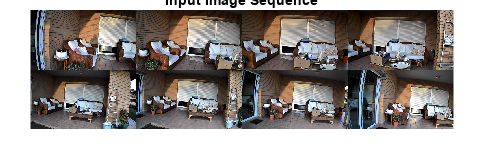

clc;
clear all;

imageDir = fullfile('Scripts/images/Left/');
imds = imageDatastore(imageDir);

figure
montage(imds.Files, 'Size', [2, 4]);
title('Input Image Sequence');


% Convert the images to grayscale.
images = cell(1, numel(imds.Files));
for i = 1:numel(imds.Files)
    I = readimage(imds, i);
    images{i} = rgb2gray(I);
end

load('calibration_support.mat');
cameraParams = stereoParams.CameraParameters1

cameraParams =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [16×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 2.0376
                 ReprojectionErrors: [48×2×16 double]
                  ReprojectedPoints: [48×2×16 double]

   Calibration Settings
                        NumPatterns: 16
                  DetectedKeypoints: [48×16 logical]
                        WorldPoints: [48×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 1
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 1


% Get intrinsic parameters of the camera
intrinsics = cameraParams.Intrinsics;

% Undistort the first image.
I = undistortImage(images{1}, intrinsics); 

% Detect features. Increasing 'NumOctaves' helps detect large-scale
% features in high-resolution images. Use an ROI to eliminate spurious
% features around the edges of the image.
border = 50;
roi = [border, border, size(I, 2)- 2*border, size(I, 1)- 2*border];
prevPoints   = detectSURFFeatures(I, 'NumOctaves',8, 'ROI',roi);

% Extract features. Using 'Upright' features improves matching, as long as
% the camera motion involves little or no in-plane rotation.
prevFeatures = extractFeatures(I, prevPoints, 'Upright',true);

% Create an empty imageviewset object to manage the data associated with each
% view.
vSet = imageviewset;

% Add the first view. Place the camera associated with the first view
% and the origin, oriented along the Z-axis.
viewId = 1;
vSet = addView(vSet, viewId, rigidtform3d, 'Points',prevPoints);


for i = 2:numel(images)
    % Undistort the current image.
    I = undistortImage(images{i}, intrinsics);
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(I, NumOctaves=8, ROI=roi);
    currFeatures = extractFeatures(I, currPoints, Upright=true);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, ...
        MaxRatio=0.7, Unique=true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
    
    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    [relPose, location, inlierIdx] = helperEstimateRelativePose(...
        matchedPoints1, matchedPoints2, intrinsics);
    relativePose = rigidtform3d(relPose, location);

     
    % Get the table containing the previous camera pose.
    prevPose = poses(vSet, i-1).AbsolutePose;
        
    % Compute the current camera pose in the global coordinate system 
    % relative to the first view.
    currPose = rigidtform3d(prevPose.A*relativePose.A);
    
    % Add the current view to the view set.
    vSet = addView(vSet, i, currPose, Points=currPoints);

%     % Store the point matches between the previous and the current views.
%     vSet = addConnection(vSet, i-1, i, relativePose, Matches=indexPairs(inlierIdx,:));
%     
%     % Find point tracks across all views.
%     tracks = findTracks(vSet);
% 
%     % Get the table containing camera poses for all views.
%     camPoses = poses(vSet);
% 
%     % Triangulate initial locations for the 3-D world points.
%     xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
%     
%     % Refine the 3-D world points and camera poses.
%     [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, ...
%         tracks, camPoses, intrinsics, FixedViewId=1, ...
%         PointsUndistorted=true);

%     % Store the refined camera poses.
%     vSet = updateView(vSet, camPoses);

    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end
camPoses = poses(vSet)

camPoses = 8×2 table
    ViewId      AbsolutePose  
    ______    ________________

      1       1×1 rigidtform3d
      2       1×1 rigidtform3d
      3       1×1 rigidtform3d
      4       1×1 rigidtform3d
      5       1×1 rigidtform3d
      6       1×1 rigidtform3d
      7       1×1 rigidtform3d
      8       1×1 rigidtform3d


% Display camera poses.
camPoses = poses(vSet)

camPoses = 8×2 table
    ViewId      AbsolutePose  
    ______    ________________

      1       1×1 rigidtform3d
      2       1×1 rigidtform3d
      3       1×1 rigidtform3d
      4       1×1 rigidtform3d
      5       1×1 rigidtform3d
      6       1×1 rigidtform3d
      7       1×1 rigidtform3d
      8       1×1 rigidtform3d


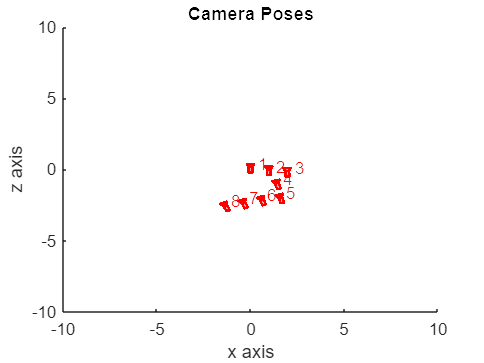

figure;
plotCamera(camPoses, Size=0.2);
view([0 0])
% Add labels to the x, y, and z axes
xlabel('x axis')
ylabel('y axis')
zlabel('z axis')
title('Camera Poses');

% % Exclude noisy 3-D points.
% goodIdx = (reprojectionErrors < 5);
% xyzPoints = xyzPoints(goodIdx, :);
% 
% % Display the 3-D points.
% pcshow(xyzPoints, MarkerSize= 45);
% grid on
% hold off

% Specify the viewing volume.
xlim([-10, 10]);
ylim([-10, 10]);
zlim([-10, 10]);